img = imread("test.jpg");

% Divide the image into 16 square pieces.
for i = 0:15
    p = fix(i / 4); q = mod(i, 4);
    
    if (i == 0)
        blocks = img(p * 128 + 1 : p * 128 + 128, q * 128 + 1 : q * 128 + 128, :);
    else
        blocks(:, :, :, i + 1) = img(p * 128 + 1 : p * 128 + 128, q * 128 + 1 : q * 128 + 128, :);
    end
end

% Find the irregularities in all pair of edges.
% The left edge and the right edge of two blocks
lr = zeros(3, 16);

for i = 1:16
    for j = 1:16
        % ith block left edge and jth block right edge
        left_block = blocks(:, :, :, i);
        right_block = blocks(:, :, :, j);
        
        % Find the five length pixel blocks at the edges and then
        % approximate the difference between average pixel values.
        l = 5; h = 16; nob = 8;
        total_diff = 0;
        
        for k = 0 : (nob - 1)
            left_average = sum(sum(blocks(k * h + 1 : (k + 1) * h, 129 - l : 128, :, i))) / (l * h);
            right_average = sum(sum(blocks(k * h + 1 : (k + 1) * h, 1 : l, :, j))) / (l * h);
            total_diff = total_diff + abs(left_average - right_average);
        end
        
        lr(1:3, i, j) = permute(total_diff, [1 3 2]);
    end
end

ud = zeros(3, 16);
for i = 1:16
    for j = 1:16
        % ith block left edge and jth block right edge
        top_block = blocks(:, :, :, i);
        bottom_block = blocks(:, :, :, j);
        
        % Find the five length pixel blocks at the edges and then
        % approximate the difference between average pixel values.
        l = 16; h = 5; nob = 8;
        total_diff = 0;
        
        for k = 0 : (nob - 1)
            top_average = sum(sum(blocks(129 - h : 128, k * l + 1 : (k + 1) * l, :, i))) / (l * h);
            bottom_average = sum(sum(blocks(1 : h, k * l + 1 : (k + 1) * l, :, j))) / (l * h);
            total_diff = total_diff + abs(left_average - right_average);
        end
        
        ud(1:3, i, j) = permute(total_diff, [1 3 2]);
    end
end

blocks_perm = randperm(16)

blocks_perm =      4    11     1    14    16     6     5     7     3    13     2     8    10     9    12    15


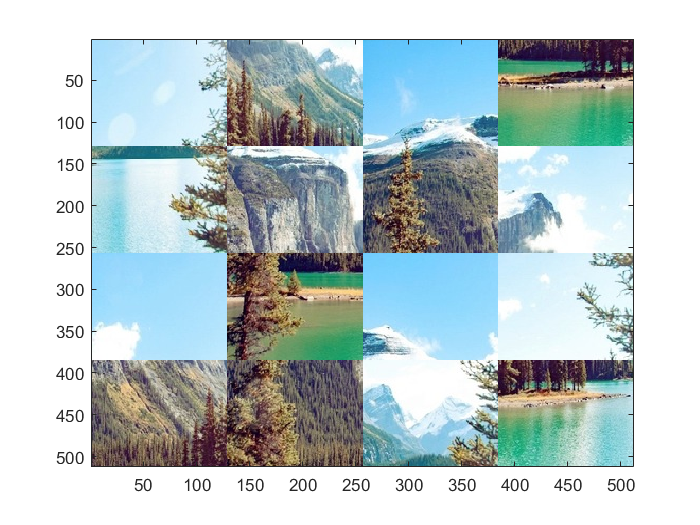

% Divide the image into 16 square pieces.
for i = 0:15
    p = fix(i / 4); q = mod(i, 4);
    
    img(p * 128 + 1 : p * 128 + 128, q * 128 + 1 : q * 128 + 128, :) = blocks(:, :, :, blocks_perm(i + 1));
end
image(img);

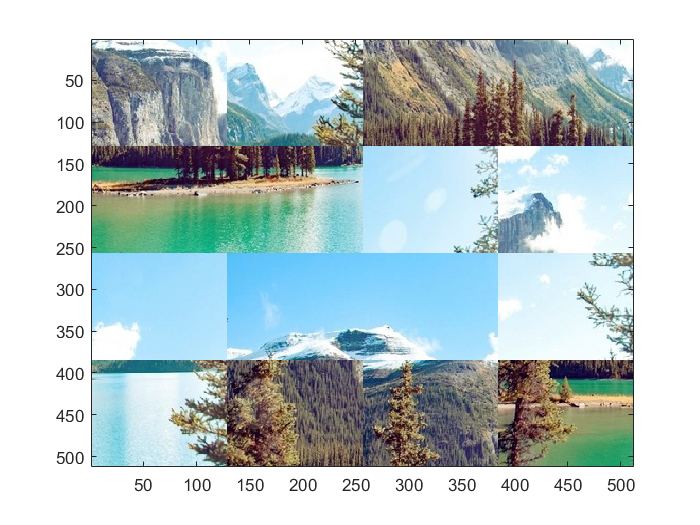


max_iter = 1000000;
c = 1000000;

for iter = 1:max_iter
    val = randi(16, 2);
    diff = sum(total_cost_change(val(1), val(2), lr, ud, blocks_perm));
    if ((diff < 0) || (rand < exp(-diff / c)))
        sw = blocks_perm(val(1));
        blocks_perm(val(1)) = blocks_perm(val(2));
        blocks_perm(val(2)) = sw;
    end
    
    c = (c + iter) / iter;
end


% Divide the image into 16 square pieces.
for i = 0:15
    p = fix(i / 4); q = mod(i, 4);
    
    img(p * 128 + 1 : p * 128 + 128, q * 128 + 1 : q * 128 + 128, :) = blocks(:, :, :, blocks_perm(i + 1));
end

image(img);

function[cost] = total_cost_change(i, j, lr, ud, blocks_perm)
cost = zeros(3, 1);

% cost change when i is swapped with j.
val = [i, j];

c1 = blocks_perm(j);
c2 = blocks_perm(i);

for s = 1:2
    im = val(s);
    tt = c1;
    c1 = c2;
    c2 = tt;
    
    if mod(im - 1, 4) ~= 0
        cost = cost + lr(:, blocks_perm(im - 1), c2) - lr(:, blocks_perm(im - 1), c1);
    end
    
    if mod(im, 4) ~= 0
        cost = cost + lr(:, c2, blocks_perm(im + 1)) - lr(:, c1, blocks_perm(im + 1));
    end
    
    if im > 4
        cost = cost + ud(:, blocks_perm(im - 4), c2) - ud(:, blocks_perm(im - 4), c1);
    end
    
    if im < 13
        cost = cost + ud(:, c2, blocks_perm(im + 4)) - ud(:, blocks_perm(im + 4), c1);
    end
end
end